

G = 28*10^9; % Shear Modulus Pa
S = 2.09;    % Strain gauge factor 
gain = 1000; % strain gauge amplifier
V_in = 15;   % input voltage in strain gauge (V)
P = 0:10:50; % input load (lbs)
T = P.*(286.66+17.4).*10^(-3).*9.81./2.205; % Torque (Nm)
%%%%%%%%%%%%%%%%%%%%%%%%% Theory %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


q1_q2 = (81/1.7+16956/49256*(81/1.7+17.4/2.34+286.66/0.32+81/1.59+17.4/2.34))/((318)/0.64+81/1.7+81*16956/(1.7*49256));
q1_T = 1/(16956*10^(-6)+49256*10^(-6)/q1_q2)

q1_T = 11.5091

q2_T = 1/(16956*10^(-6)*q1_q2+49256*10^(-6))

q2_T = 16.3402

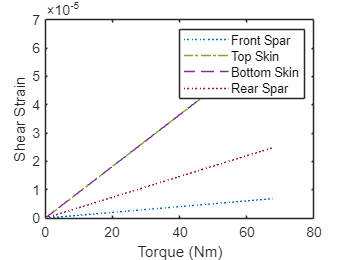

theta_dash = (q1_T/0.64*(318)+(q1_T-q2_T)*81/1.7)/(16956*10^(-6)*28*10^9);
G_theta_dash = (q1_T/0.64*(318)+(q1_T-q2_T)*81/1.7)/(16956*10^(-6));

% Theoretical Shear Strain
gamma_1_8_ext = T.*(q1_T/(G*0.64*10^(-3)));  
gamma_1_8_int = T.*((q2_T-q1_T)/(G*1.7*10^(-3)));
gamma_2_1 = T.*(q2_T/(G*2.34*10^(-3)));
gamma_3_2 = T.*(q2_T/(G*0.64*10^(-3)));
gamma_6_3 = T.*(q2_T/(G*1.59*10^(-3)));
gamma_7_6 = T.*(q2_T/(G*0.64*10^(-3)));
gamma_8_7 = T.*(q2_T/(G*2.34*10^(-3)));

%%%%%%%%%%%%% Theoretical Load vs Shear Strain %%%%%%%%%%%%%%%%%%%%%%%
figure

% Only plotting shear strain measured in the experiment

plot(T,gamma_1_8_int, ':', 'Color', [0 0.4470 0.7410])
hold on
plot(T,gamma_3_2 , '-.', 'Color', [0.4660 0.6740 0.1880])

plot(T,gamma_7_6, '--', 'Color', [0.4940 0.1840 0.5560])
plot(T,gamma_6_3,':','Color',[0.6350 0.0780 0.1840])


hold off

legend("Front Spar","Top Skin","Bottom Skin","Rear Spar")

xlabel("Torque (Nm)")
ylabel("Shear Strain")



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%%%%%% Experiment %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
V_bar_out_func = @(loadedReading, unloadedReading) (loadedReading-unloadedReading); % V out without parallex
strain_func = @(V_bar_out) (4*V_bar_out)/(V_in*S*gain); % strain for each gauge

inputData = readtable("inputSheet.csv");

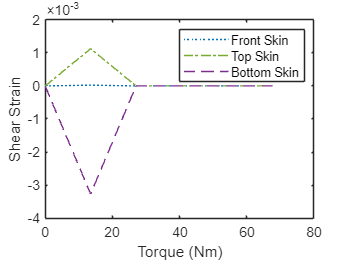


frontLoad = table2array(inputData(1:end,2));
frontUnload = table2array(inputData(1:end,3));
rearLoad = table2array(inputData(1:end,4));
rearUnload = table2array(inputData(1:end,5));
thetas = table2array(inputData(1:end,6));
thetas = deg2rad(thetas);


% c,d,e,f,g,h,i,j,k
frontStrain = zeros(size(frontLoad));
rearStrain = zeros(size(frontLoad));

for i = 1:length(frontLoad)
    frontStrain(i) = strain_func(V_bar_out_func(frontLoad(i),frontUnload(i)));
    rearStrain(i) = strain_func(V_bar_out_func(rearLoad(i),rearUnload(i)));
end

A_cde = [cos(thetas(1))^2 sin(thetas(1))^2 sin(thetas(1))*cos(thetas(1));
         cos(thetas(2))^2 sin(thetas(2))^2 sin(thetas(2))*cos(thetas(2));
         cos(thetas(3))^2 sin(thetas(3))^2 sin(thetas(3))*cos(thetas(3))];

A_fgh = [cos(thetas(4))^2 sin(thetas(4))^2 sin(thetas(4))*cos(thetas(4));
         cos(thetas(5))^2 sin(thetas(5))^2 sin(thetas(5))*cos(thetas(5));
         cos(thetas(6))^2 sin(thetas(6))^2 sin(thetas(6))*cos(thetas(6))];

A_ijk = [cos(thetas(7))^2 sin(thetas(7))^2 sin(thetas(7))*cos(thetas(7));
         cos(thetas(8))^2 sin(thetas(8))^2 sin(thetas(8))*cos(thetas(8));
         cos(thetas(9))^2 sin(thetas(9))^2 sin(thetas(9))*cos(thetas(9))];

shearStrain_cde_front_load = zeros(size(frontLoad(1:6)));
shearStrain_fgh_front_load = zeros(size(frontLoad(1:6)));
shearStrain_ijk_front_load = zeros(size(frontLoad(1:6)));

shearStrain_cde_rear_load = zeros(size(frontLoad(1:6)));
shearStrain_fgh_rear_load = zeros(size(frontLoad(1:6)));
shearStrain_ijk_rear_load = zeros(size(frontLoad(1:6)));
%%%%%%%%%%%% Load = 10 %%%%%%%%%%%%%%%%%%%
shearStrain_cde_front = A_cde \ frontStrain(1:3);
shearStrain_fgh_front = A_fgh \ frontStrain(4:6);
shearStrain_ijk_front = A_ijk \ frontStrain(7:9);

shearStrain_cde_rear = A_cde \ rearStrain(1:3);
shearStrain_fgh_rear = A_fgh \ rearStrain(4:6);
shearStrain_ijk_rear = A_ijk \ rearStrain(7:9);

shearStrain_cde_front_load(2) = shearStrain_cde_front(3);
shearStrain_fgh_front_load(2) = shearStrain_fgh_front(3);
shearStrain_ijk_front_load(2) = shearStrain_ijk_front(3);

shearStrain_cde_rear_load(2) = shearStrain_cde_rear(3);
shearStrain_fgh_rear_load(2) = shearStrain_fgh_rear(3);
shearStrain_ijk_rear_load(2) = shearStrain_ijk_rear(3);

%%%%%%%%%%%% Load = 20 %%%%%%%%%%%%%%%%%%%
shearStrain_cde_front = A_cde \ frontStrain(10:12);
shearStrain_fgh_front = A_fgh \ frontStrain(13:15);
shearStrain_ijk_front = A_ijk \ frontStrain(16:18);

shearStrain_cde_rear = A_cde \ rearStrain(10:12);
shearStrain_fgh_rear = A_fgh \ rearStrain(13:15);
shearStrain_ijk_rear = A_ijk \ rearStrain(16:18);

shearStrain_cde_front_load(3) = shearStrain_cde_front(3);
shearStrain_fgh_front_load(3) = shearStrain_fgh_front(3);
shearStrain_ijk_front_load(3) = shearStrain_ijk_front(3);

shearStrain_cde_rear_load(3) = shearStrain_cde_rear(3);
shearStrain_fgh_rear_load(3) = shearStrain_fgh_rear(3);
shearStrain_ijk_rear_load(3) = shearStrain_ijk_rear(3);


%%%%%%%%%%%% Load = 30 %%%%%%%%%%%%%%%%%%%
shearStrain_cde_front = A_cde \ frontStrain(19:21);
shearStrain_fgh_front = A_fgh \ frontStrain(22:24);
shearStrain_ijk_front = A_ijk \ frontStrain(25:27);

shearStrain_cde_rear = A_cde \ rearStrain(19:21);
shearStrain_fgh_rear = A_fgh \ rearStrain(22:24);
shearStrain_ijk_rear = A_ijk \ rearStrain(25:27);

shearStrain_cde_front_load(4) = shearStrain_cde_front(3);
shearStrain_fgh_front_load(4) = shearStrain_fgh_front(3);
shearStrain_ijk_front_load(4) = shearStrain_ijk_front(3);

shearStrain_cde_rear_load(4) = shearStrain_cde_rear(3);
shearStrain_fgh_rear_load(4) = shearStrain_fgh_rear(3);
shearStrain_ijk_rear_load(4) = shearStrain_ijk_rear(3);

%%%%%%%%%%%% Load = 40 %%%%%%%%%%%%%%%%%%%
shearStrain_cde_front = A_cde \ frontStrain(28:30);
shearStrain_fgh_front = A_fgh \ frontStrain(31:33);
shearStrain_ijk_front = A_ijk \ frontStrain(34:36);

shearStrain_cde_rear = A_cde \ rearStrain(28:30);
shearStrain_fgh_rear = A_fgh \ rearStrain(31:33);
shearStrain_ijk_rear = A_ijk \ rearStrain(34:36);

shearStrain_cde_front_load(5) = shearStrain_cde_front(3);
shearStrain_fgh_front_load(5) = shearStrain_fgh_front(3);
shearStrain_ijk_front_load(5) = shearStrain_ijk_front(3);

shearStrain_cde_rear_load(5) = shearStrain_cde_rear(3);
shearStrain_fgh_rear_load(5) = shearStrain_fgh_rear(3);
shearStrain_ijk_rear_load(5) = shearStrain_ijk_rear(3);


%%%%%%%%%%%% Load = 50 %%%%%%%%%%%%%%%%%%%
shearStrain_cde_front = A_cde \ frontStrain(37:39);
shearStrain_fgh_front = A_fgh \ frontStrain(40:42);
shearStrain_ijk_front = A_ijk \ frontStrain(43:45);

shearStrain_cde_rear = A_cde \ rearStrain(37:39);
shearStrain_fgh_rear = A_fgh \ rearStrain(40:42);
shearStrain_ijk_rear = A_ijk \ rearStrain(43:45);

shearStrain_cde_front_load(6) = shearStrain_cde_front(3);
shearStrain_fgh_front_load(6) = shearStrain_fgh_front(3);
shearStrain_ijk_front_load(6) = shearStrain_ijk_front(3);

shearStrain_cde_rear_load(6) = shearStrain_cde_rear(3);
shearStrain_fgh_rear_load(6) = shearStrain_fgh_rear(3);
shearStrain_ijk_rear_load(6) = shearStrain_ijk_rear(3);

%%%%%%%%%%%%% Load vs Shear Strain %%%%%%%%%%%%%%%%%%%%%%%
figure


plot(T,shearStrain_cde_rear_load - shearStrain_cde_front_load, ':', 'Color', [0 0.4470 0.7410])
hold on
plot(T,shearStrain_fgh_rear_load - shearStrain_fgh_front_load, '-.', 'Color', [0.4660 0.6740 0.1880])

plot(T,shearStrain_ijk_rear_load - shearStrain_ijk_front_load, '--', 'Color', [0.4940 0.1840 0.5560])


hold off

legend("Front Skin","Top Skin","Bottom Skin")

xlabel("Torque (Nm)")
ylabel("Shear Strain")